f = @(t)(cos((pi * t.^2) / 2));
a = 0;
b = pi;
n1 = 10.^3;
n2 = 10.^5;

I1 = composite_trapezoid(f, a, b, n1)

I1 =    0.523696892637853


I2 = composite_trapezoid(f, a, b, n2)

I2 =    0.523698543561136


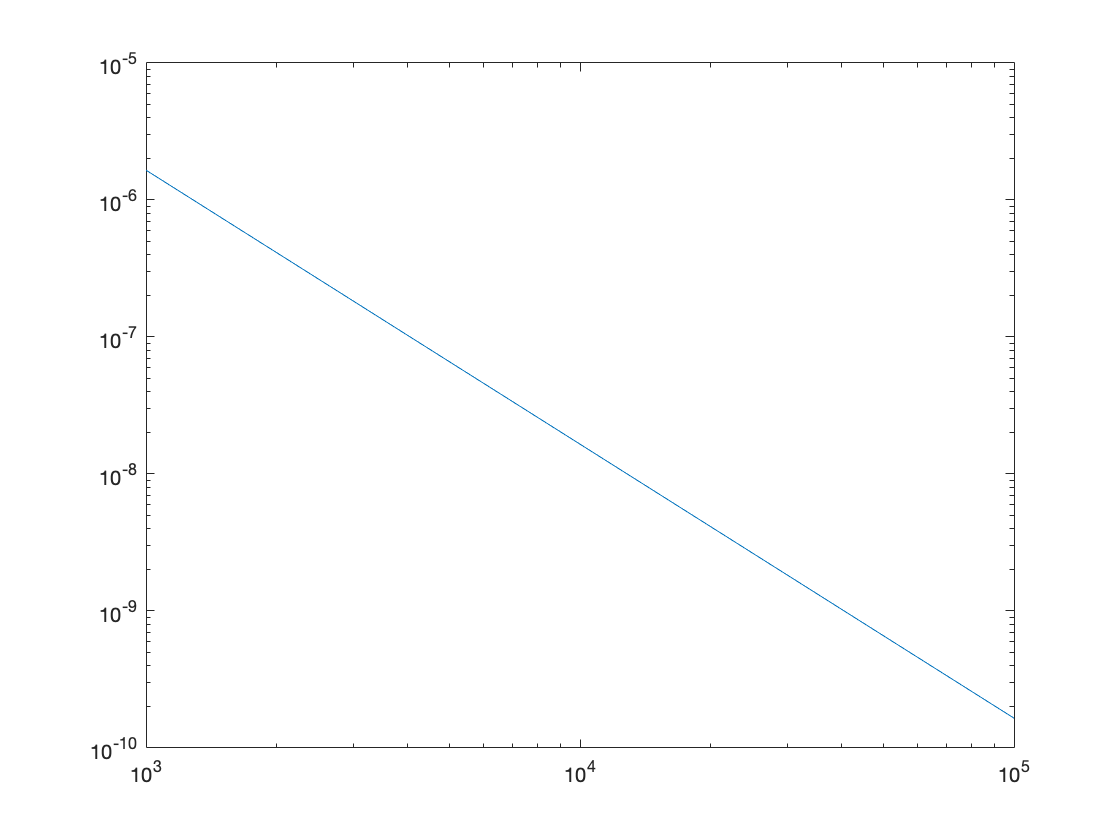


ExactSol = fresnelc(pi);
% fresnelc(pi) = 0.523698543726229

Err1 = abs(I1 - ExactSol);
Err2 = abs(I2 - ExactSol);

% Err1 = 1.651088376020127e-06
% Err2 = 1.650930503416248e-10


loglog([n1,n2],[Err1, Err2])

function I = composite_trapezoid(f, a, b, n)
h = (b - a) / n;

I = f(a) + f(b);

for i = 1:n-1
    I = I + 2 * f(a + i * h); 
    
end
I = (h / 2) * I;
end